# Primera Prueba

Generar un vector de datos

%ruta_1 = [VSSf,TPSf,MAPf,O2f,STFTf,LTFTf,IATf,ECTf,Tiempo...
%           RPMSf,Tf'];
%filename = 'ruta_1';
%save(filename)
load('ruta_1.mat')

**Generación del mapa de Ruta**

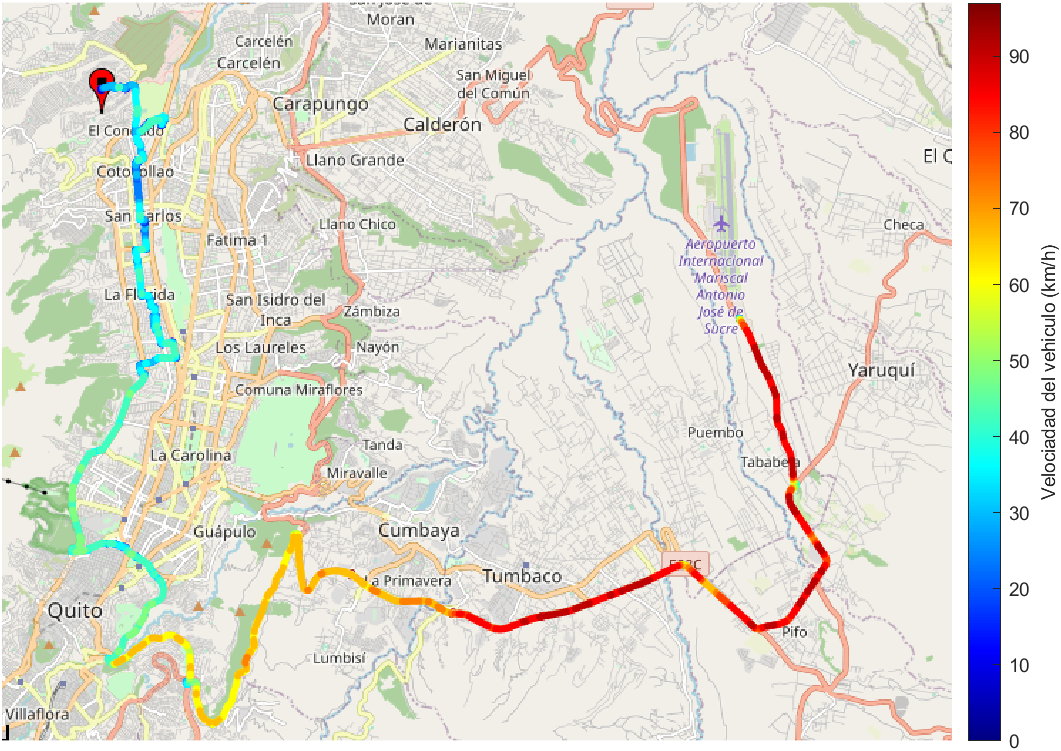

Validación de datos

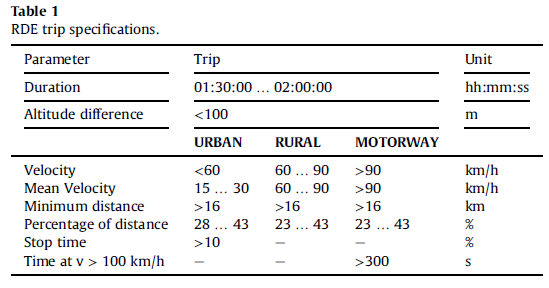

TTR=(Tf(end)/1000);
Duracion=TTR/60 %minutos

Duracion = 103.7867

Verificacion de distancias

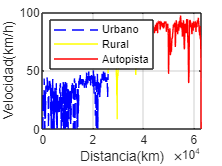

urbano = (1:56642);
interurbano = (56643:69377);
rural = (69378:80609);
figure()
v_1 = VSSf(urbano,:);
distancia_t = cumtrapz(T/1000,VSSf/3.6);
dist_1 = distancia_t(urbano,:);
plot(dist_1,v_1,'b--','DisplayName','Urbano')
xlabel("Distancia(km)")
ylabel("Velocidad(km/h)")
grid
hold on
v_2 = VSSf(interurbano,:);
dist_2 = distancia_t(interurbano,:);
plot(dist_2,v_2,'y','DisplayName','Rural')
hold on
v_3 = VSSf(rural,:);
dist_3 = distancia_t(rural,:);
plot(dist_3,v_3,'r','DisplayName','Autopista')
legend(("show"), Location="northwest")

Distancias totales

t_1=Tf(:,urbano);
t_2=Tf(:,interurbano);
t_3=Tf(:,rural);
distancia_urb=(trapz(t_1/1000,v_1/3.6))/1000

distancia_urb = 25.8705

distancia_inter=(trapz(t_2/1000,v_2/3.6))/1000

distancia_inter = 17.0917

distancia_aut=(trapz(t_3/1000,v_3/3.6))/1000

distancia_aut = 19.8406

cumptrapz es la integral acumulada

trapz es la integral total

# **Porcentaje de distancias**

porcentaje_urb=(distancia_urb*100)/(dist_r/1000)

porcentaje_urb = 41.1928

porcentaje_inter=(distancia_inter*100)/(dist_r/1000)

porcentaje_inter = 27.2146

porcentaje_aut=(distancia_aut*100)/(dist_r/1000)

porcentaje_aut = 31.5915

Tiempo de parada en el tramo urbano

t_parada = find (v_1 == 0);
porcentaje_parada = (length(t_parada)/length(v_1))*100

porcentaje_parada = 26.3426

Velocidad promedio

velocidad_urb = mean(v_1)

velocidad_urb = 21.2562

velocidad_inteurb = mean(v_2)

velocidad_inteurb = 62.5037

velocidad_aut = mean(v_3)

velocidad_aut = 82.2748

Analisis Factorial (No olvidar que la corrida es aleatoria) 

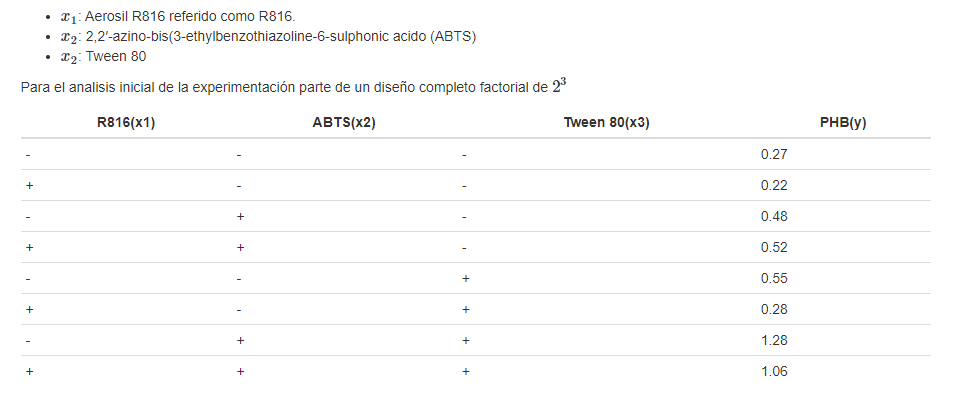

Vector aleatorio

aleatorio = [1 2 3 4 5 6 7 8];
a_rand = aleatorio(randperm(length(aleatorio)))

a_rand =      6     1     5     3     7     2     8     4
